clear all
syms lambda rA rB R1 R2 R3 uA3 uB3 ;

r1=[3.87;-6.69;-7.76];
u31=[0;0;1];
r2=[-7.73;0;0];
u32=[0;0;1];
r3=[3.87;6.69;7.76];
u33=[0;0;1];
r4=[-7.73;0;-11.81];
u34=[0;0;-1];
r5=[3.87;6.69;-4.05];
u35=[0;0;-1];
r6=[3.87;-6.69;3.70];
u36=[0;0;-1];

x1=[];
y1=[];
x2=[];
y2=[];
x3=[];
y3=[];
x4=[];
y4=[];
x5=[];
y5=[];
x6=[];
y6=[];
x7=[];
y7=[];

% center and direction of spheroids

hold on
axis([5 15 5 15]);
for R3=5:0.3:15 %离心率
    R1=10;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r1,r2,R1,R3,u31,u32);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r2,R1,R3,u31,u32);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r2,R1,R3,u31,u32);
    end
    [R1,R3,miu2]
    x1=[x1,R1];
    y1=[y1,R3]; 
end

ans =    10.6100    5.0000    1.0004


ans =     9.8200    5.3000    1.0008


ans =     9.2800    5.6000    1.0006


ans =     8.8800    5.9000    1.0010


ans =     8.5800    6.2000    1.0006


ans =     8.3400    6.5000    1.0008


ans =     8.1500    6.8000    1.0005


ans =     7.9900    7.1000    1.0008


ans =     7.8600    7.4000    1.0005


ans =     7.7500    7.7000    1.0003


ans =     7.6500    8.0000    1.0012


ans =     7.5700    8.3000    1.0008


ans =     7.5000    8.6000    1.0005


ans =     7.4300    8.9000    1.0021


ans =     7.3800    9.2000    1.0010


ans =     7.3300    9.5000    1.0012


ans =     7.2900    9.8000    1.0003


ans =     7.2500   10.1000    1.0004


ans =     7.2100   10.4000    1.0015


ans =     7.1800   10.7000    1.0011


ans =     7.1500   11.0000    1.0013


ans =     7.1200   11.3000    1.0022


ans =     7.1000   11.6000    1.0012


ans =     7.0800   11.9000    1.0006


ans =     7.0600   12.2000    1.0005


ans =     7.0400   12.5000    1.0009


ans =     7.0200   12.8000    1.0016


ans =     7.0000   13.1000    1.0026


ans =     6.9900   13.4000    1.0013


ans =     6.9800   13.7000    1.0003


ans =     6.9600   14.0000    1.0022


ans =     6.9500   14.3000    1.0017


ans =     6.9400   14.6000    1.0014


ans =     6.9300   14.9000    1.0013


plot(x1,y1,'color',[221, 42, 22]/256, ...
    'LineWidth',1.5,'DisplayName','1-2')


for R1=5:0.3:15 %离心率
    R3=5.6;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r2,r4,R1,R3,u32,u34);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1;
        R3=R3+n;
        miu2=cont(r2,r4,R1,R3,u32,u34);
    end
    
    while miu2<1
        R1=R1;
        R3=R3-n;
        miu2=cont(r2,r4,R1,R3,u32,u34);
    end
    [R1,R3,miu2]
    x2=[x2,R1];
    y2=[y2,R3]; 
end

ans =     5.0000    5.9000    1.0017


ans =     5.3000    5.9000    1.0017


ans =     5.6000    5.9000    1.0017


ans =     5.9000    5.9000    1.0017


ans =     6.2000    5.9000    1.0017


ans =     6.5000    5.9000    1.0017


ans =     6.8000    5.9000    1.0017


ans =     7.1000    5.9000    1.0017


ans =     7.4000    5.9000    1.0017


ans =     7.7000    5.9000    1.0017


ans =     8.0000    5.9000    1.0017


ans =     8.3000    5.9000    1.0017


ans =     8.6000    5.9000    1.0017


ans =     8.9000    5.9000    1.0017


ans =     9.2000    5.9000    1.0017


ans =     9.5000    5.9000    1.0017


ans = 1×3
    9.8000    5.9000    1.0017


ans = 1×3
   10.1000    5.9000    1.0017


ans = 1×3
   10.4000    5.9000    1.0017


ans = 1×3
   10.7000    5.9000    1.0017


ans = 1×3
   11.0000    5.9000    1.0017


ans = 1×3
   11.3000    5.9000    1.0017


ans = 1×3
   11.6000    5.9000    1.0017


ans = 1×3
   11.9000    5.9000    1.0017


ans = 1×3
   12.2000    5.9000    1.0017


ans = 1×3
   12.5000    5.9000    1.0017


ans = 1×3
   12.8000    5.9000    1.0017


ans = 1×3
   13.1000    5.9000    1.0017


ans = 1×3
   13.4000    5.9000    1.0017


ans = 1×3
   13.7000    5.9000    1.0017


ans = 1×3
   14.0000    5.9000    1.0017


ans = 1×3
   14.3000    5.9000    1.0017


ans = 1×3
   14.6000    5.9000    1.0017


ans = 1×3
   14.9000    5.9000    1.0017


plot(x2,y2,'color',[29, 50, 67]/256, ...
    'LineWidth',1.5,'DisplayName','2-4')


for R1=5:0.3:15 %离心率
    R3=5.6;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r1,r6,R1,R3,u31,u36);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1;
        R3=R3+n;
        miu2=cont(r1,r6,R1,R3,u31,u36);
    end
    
    while miu2<1
        R1=R1;
        R3=R3-n;
        miu2=cont(r1,r6,R1,R3,u31,u36);
    end
    [R1,R3,miu2]
    x3=[x3,R1];
    y3=[y3,R3];  
end

ans = 1×3
    5.0000    5.7300    1.0000


ans = 1×3
    5.3000    5.7300    1.0000


ans = 1×3
    5.6000    5.7300    1.0000


ans = 1×3
    5.9000    5.7300    1.0000


ans = 1×3
    6.2000    5.7300    1.0000


ans = 1×3
    6.5000    5.7300    1.0000


ans = 1×3
    6.8000    5.7300    1.0000


ans = 1×3
    7.1000    5.7300    1.0000


ans = 1×3
    7.4000    5.7300    1.0000


ans = 1×3
    7.7000    5.7300    1.0000


ans = 1×3
    8.0000    5.7300    1.0000


ans = 1×3
    8.3000    5.7300    1.0000


ans = 1×3
    8.6000    5.7300    1.0000


ans = 1×3
    8.9000    5.7300    1.0000


ans = 1×3
    9.2000    5.7300    1.0000


ans = 1×3
    9.5000    5.7300    1.0000


ans = 1×3
    9.8000    5.7300    1.0000


ans = 1×3
   10.1000    5.7300    1.0000


ans = 1×3
   10.4000    5.7300    1.0000


ans = 1×3
   10.7000    5.7300    1.0000


ans = 1×3
   11.0000    5.7300    1.0000


ans = 1×3
   11.3000    5.7300    1.0000


ans = 1×3
   11.6000    5.7300    1.0000


ans = 1×3
   11.9000    5.7300    1.0000


ans = 1×3
   12.2000    5.7300    1.0000


ans = 1×3
   12.5000    5.7300    1.0000


ans = 1×3
   12.8000    5.7300    1.0000


ans = 1×3
   13.1000    5.7300    1.0000


ans = 1×3
   13.4000    5.7300    1.0000


ans = 1×3
   13.7000    5.7300    1.0000


ans = 1×3
   14.0000    5.7300    1.0000


ans = 1×3
   14.3000    5.7300    1.0000


ans = 1×3
   14.6000    5.7300    1.0000


ans = 1×3
   14.9000    5.7300    1.0000


plot(x3,y3,'color',[151, 150, 159]/256, ...
    'LineWidth',1.5,'DisplayName','1-6')

for R3=5:0.3:15 %离心率
    R1=10;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r2,r5,R1,R3,u32,u35);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r2,r5,R1,R3,u32,u35);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r2,r5,R1,R3,u32,u35);
    end
    [R1,R3,miu2]
    x4=[x4,R1];
    y4=[y4,R3];  
end

ans = 1×3
    7.3200    5.0000    1.0007


ans = 1×3
    7.2400    5.3000    1.0012


ans = 1×3
    7.1800    5.6000    1.0003


ans = 1×3
    7.1200    5.9000    1.0021


ans = 1×3
    7.0800    6.2000    1.0010


ans = 1×3
    7.0400    6.5000    1.0016


ans = 1×3
    7.0100    6.8000    1.0010


ans = 1×3
    6.9800    7.1000    1.0015


ans = 1×3
    6.9600    7.4000    1.0003


ans = 1×3
    6.9300    7.7000    1.0026


ans = 1×3
    6.9200    8.0000    1.0002


ans = 1×3
    6.9000    8.3000    1.0011


ans = 1×3
    6.8800    8.6000    1.0025


ans = 1×3
    6.8700    8.9000    1.0016


ans = 1×3
    6.8600    9.2000    1.0010


ans = 1×3
    6.8500    9.5000    1.0008


ans = 1×3
    6.8400    9.8000    1.0009


ans = 1×3
    6.8300   10.1000    1.0012


ans = 1×3
    6.8200   10.4000    1.0017


ans = 1×3
    6.8100   10.7000    1.0025


ans = 1×3
    6.8100   11.0000    1.0005


ans = 1×3
    6.8000   11.3000    1.0016


ans = 1×3
    6.7900   11.6000    1.0028


ans = 1×3
    6.7900   11.9000    1.0013


ans = 1×3
    6.7800   12.2000    1.0028


ans = 1×3
    6.7800   12.5000    1.0015


ans = 1×3
    6.7800   12.8000    1.0002


ans = 1×3
    6.7700   13.1000    1.0020


ans = 1×3
    6.7700   13.4000    1.0009


ans = 1×3
    6.7600   13.7000    1.0028


ans = 1×3
    6.7600   14.0000    1.0019


ans = 1×3
    6.7600   14.3000    1.0010


ans = 1×3
    6.7600   14.6000    1.0002


ans = 1×3
    6.7500   14.9000    1.0024


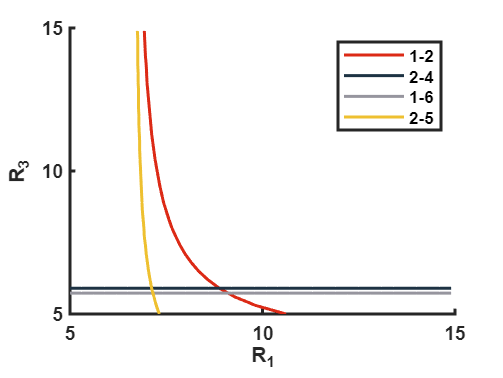

plot(x4,y4,'color',[239, 193, 48]/256, ...
    'LineWidth',1.5,'DisplayName','2-5')

hold off

set(gca,'linewidth',1.5,'FontWeight','bold','FontName','arial');
xlabel('R_1','FontName','arial','FontWeight','bold'); 
ylabel('R_3','FontName','arial','FontWeight','bold');
legend('Location','northeast');

function miu2=cont(rA,rB,R1,R3,uA3,uB3)
    syms lambda
    rAB=rB-rA;
    e=R3/R1;
    x=(1-lambda)*(1-e^2);
    y=lambda*(1-e^2);
    D=(1-x)*(1-y)-x*y*(dot(uA3,uB3))^2;
    alpha=x*(1-y)/D;
    beta=y*(1-x)/D;
    gama=x*y*(dot(uA3,uB3))/D;
    I=eye(3);
    C=(I+alpha*(uA3*uA3.')+beta*(uB3*uB3.')+gama*((uA3*uB3.')+(uB3*uA3.')))/(R1^2);
    F=lambda*(1-lambda)*(rAB.'*C*rAB);
    fun=@(lambda) -eval(F);
    [~,fval]=fminbnd(fun,0,1);
    miu2=-fval;
end

